# Raíces de una función

## 3.1 Entendiendo las distintas metodologías

### 3.1.1 Newton-Rpahson

El algoritmo de Newton-Raphson permite encontrar la raíz de una función partiendo desde un punto del dominio cercano a dicha raíz. Es un método **iterativo** y preciso que es útil sobre polinomios de grado *impar*. Desde una aproximación de **Taylor** de primer orden es posible obtener la siguiente sucesión que define el algortimo. Es importante notar que  dos valores consecutivos de la sucesión serán cada vez más similares en la medida en que se aproximen a la raíz de la función :


$$x_{n+1} \;=x_n$$

$$=\frac{\;f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$
  

Con $x_o \;\textrm{conocido}\ldotp \;$La figura adjunta en el enunciado explica de forma gráfica el método de estudio

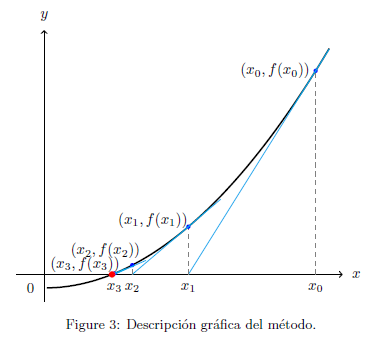

### 3.1.2 Algoritmo de Bisección

Basado en el teorema de los Valores Intermedios, el algoritmo de Bisección establece: 

Sea$\begin{array}{l}
f:\left\lbrack a,b\right\rbrack \longrightarrow R\;\mathrm{una}\;\mathrm{función}\;\mathrm{continua}\;{\mathrm{diferenciable}\;C}^{1\;} \;\mathrm{donde}\;\mathrm{todo}\;\mathrm{valor}\;\mathrm{entre}\;f\left(a\right)\;\;y\;f\left(b\right)\;\mathrm{es}\;\mathrm{imagen}\;\mathrm{de}\;\mathrm{al}\;\mathrm{menos}\;\mathrm{un}\;\mathrm{valor}\;\mathrm{del}\;\mathrm{intervalo}\;\left\lbrack a,b\right\rbrack \ldotp \\
\mathrm{Luego},\mathrm{si}\;f\left(a\right)\;y\;\;f\left(b\right)\;\mathrm{tienen}\;\mathrm{signos}\;\mathrm{opuestos}\;\left(f\left(a\right)\cdot f\left(b\right)<0\right),\mathrm{el}\;\mathrm{teorema}\;\mathrm{asegura}\;\mathrm{la}\;\mathrm{existencia}\;\mathrm{de}\;\mathrm{al}\;\mathrm{menos}\;\mathrm{un}\;\mathrm{valor}\;x\;\mathrm{del}\;\mathrm{dominio}\;\mathrm{de}\;\mathrm{la}\;\mathrm{función}\;\mathrm{que}\;\mathrm{cumple}\;f\left(x\right)=0\;
\end{array}$

Para programar el algoritmo de Bisección siga los siguientes pasos

- Compute una tolerancia $\tau =10{\;}^{-4}$ y defina un intervalo [a,b] que contenga la raíz de la función.

- Dada una función que cumpla con las características, compute f(a) y f(b)

- Compute $\bar{r} =\frac{a+b}{2}$ y luego obtenga $f\left(\bar{r} \right)$. Si el signo de  $f\left(\bar{r} \right)$ es igual al signo  $f\left(a\right)$, entonces el nuevo intervalo definido en el dominio de la función seá  $\left\lbrack \bar{\;r} ,b\;\right\rbrack \;\textrm{de}\;\textrm{otra}\;\textrm{forma}\;\textrm{el}\;\textrm{nuevo}\;\textrm{intervalo}\;\textrm{será}\;\left\lbrack a,\bar{\;r} \right\rbrack \ldotp$

- Compute el error de aproximación  $\epsilon =f\left(\bar{\;r} \right)$

- Mientras  $\epsilon >\tau \;$ repita el proceso hasta que el algoritmo converja a la tolerancia deseada

Generalmente el algoritmo de bisección no produce una solución exacta a la ecuación f(x)=0. Ahora bien, se puede proveer de una estimación sobre el error absoluto. El teorema es el siguiente.

Teorema. Sea f(x) una función continua entre [a,b] tal que f(a)f(b) < 0. Luego de N iteraciones del método de bisección, sea $\left\lbrack X_n \right\rbrack$ el punto intermedio en el subintervalo n-ésimo $\left\lbrack a_n ,b_n \right\rbrack$


$$X_n =\frac{a_n +b_n }{2}$$


Entonces, existe una solución exacta y verdadera de la ecuación $f\left(x\right)=0$ en el subintervalo $\left\lbrack a_n ,b_n \right\rbrack$ y el error absoluto es


$$\epsilon >\left\lbrack x*-x_n \right\rbrack \le \frac{b-a}{2^{\;n+1} }$$


Notemos que podemos reorganizar el límite del error de modo de poder notificar cuál es el número mínimo de iteraciones requeridas para garantizar que el error absoluto sea menor al descrito


$$\begin{array}{l}
\frac{b-a}{2^{\;n+1} }<\epsilon \\
\frac{b-a}{\epsilon }<2^{\;n+1} \\
\ln \frac{b-a}{\epsilon }<n+1\cdot \ln \left(2\right)\\
\frac{\ln \frac{b-a}{\epsilon }}{\ln \left(2\right)}\;-\;1<n
\end{array}$$



epsilon = f(r0); 
i=0;    
while epsilon>tol
i=i+1;
fa= a0*x + a0*y; 
fb= b0*x + b0*y; 
XX(i,1)=fa;
YY(i,1)=fb;
a0=fa;
b0=fb;
end

F=['Solucion: ',num2str(x0),' ',num2str(y0), 'Iteraciones', i ] 
figure(2)
plot(XX);
grid on;
title('Convergencia del sistema al equilibrio')
set(gcf,'color','w');

Responda las siguientes presuentas

(a) Usando el método Newton-Raphson, encuentra la raiz de las siguientes funciones

 
$$\begin{array}{l}
f\left(x\right)=x^{3\;} +x+2\\
f\left(x\right)=x^{5\;} +x^4 +x^3 +x^2 +1\\
f\left(x\right)=\log \left(x\right)+\log \left(3x^3 \right)
\end{array}$$
 

Adicional, hacer gráfico

(b) Obtenga la raíz de las funciones usando el algoritmo de Bisección. ¿Obtiene los mismos resultados?

(c) ¿Cuál algoritmo es más eficiente? Justifique brevemente

(d) Cree las funciones NR y BS que permite encontrar las raíces de una función con características indicadas mediante el método Newton-Raphson y Bisección respectivamente. Utilice las funciones para computar raíces de los incisos anteriores nuevamente. 